**Exercise 1 part (ii):**

Physical meaning of each equation:

- The change in concentration of A (mg/L) at the outlet of reactor 1  with respect to time (minutes) that enters reactor 2 will be given by the amount of concentration of A that will be in the reactor during the residence time ($\frac{\left({\mathrm{CA}}_0 -{\mathrm{CA}}_1 \right)}{\tau }$ ) minus the amount of A that is reacting into B as time passes (${\mathrm{kCA}}_1$) .

- The change in concentration of B (mg/L) with respect to time (minutes), at the outlet of reactor 1 and going into reactor 2 is given by the amount of A that reacted to B that is in the outlet of reactor 1 (${\mathrm{kCA}}_1$) minus the amount of B that is inside the reactor ($\frac{{\mathrm{CB}}_1 }{\tau }$).

- The change in concentration of A (mg/L) with respect to time (minutes) at the outlet of reactor 2 is given by the amount of time A is inside the reactor 2 ($\frac{\left({\mathrm{CA}}_1 -{\mathrm{CA}}_2 \right)}{\tau }$) minus the amount of A in the outlet of Reactor 2 that is reacting into B as time passes (${\mathrm{kCA}}_2$).

- The change in concentration of B (mg/L) at the outlet of reactor 2 with respect to time (minutes) is given by the the amount of A at the outlet of reactor 2 that is reacting into B as time passes (${\mathrm{kCA}}_2$) and the amount of B that is inside reactor 2 ($\frac{\left({\mathrm{CB}}_1 -{\mathrm{CB}}_2 \right)}{\tau }$). 

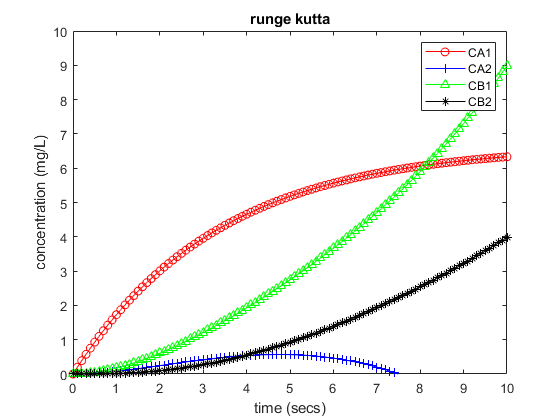

c0 = [0; 0; 0; 0]; % initial condition
t = [0:0.1:10];
[c] = runge_kutta(@chemical_reactor,t,c0);
c1=c(1,:);
c2=c(2,:);
c3=c(3,:);
c4=c(4,:);

% runge kutta:
figure(1)
plot(t,c1,'-ro',t,c2,'-b+',t,c3,'-g^',t,c4,'-k*')
legend('CA1','CA2','CB1','CB2');
xlabel('time (secs)');
ylabel('concentration (mg/L)');
title('runge kutta')
hold off;
ylim([0,10])

% ode 45:
figure(2)
ode45(@chemical_reactor,[0 10],c0)

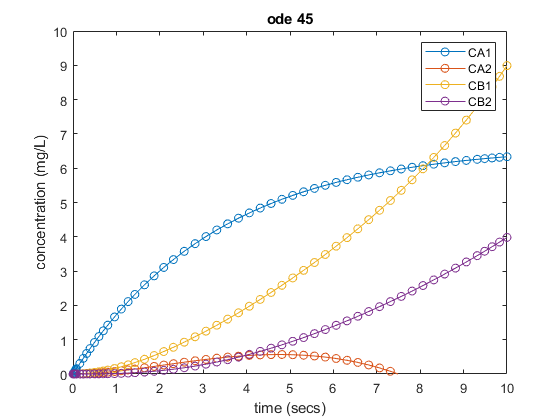

legend('CA1','CA2','CB1','CB2');
title('ode 45');
xlabel('time (secs)');
ylabel('concentration (mg/L)');
ylim([0,10]);

% both
figure(3)
plot(t,c1,'-ro',t,c2,'-b+',t,c3,'-g^',t,c4,'-k*');
xlabel('time (secs)');
ylabel('concentration (mg/L)');
hold on
ode45(@chemical_reactor,[0 10],c0)

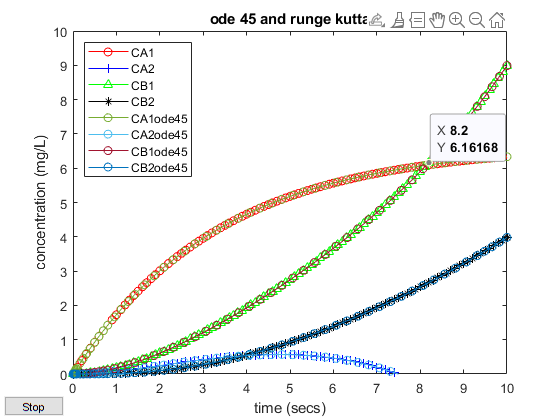

title('ode 45 and runge kutta');
ylim([0,10])
legend('CA1','CA2','CB1','CB2','CA1ode45','CA2ode45','CB1ode45','CB2ode45','Location','northwest');

function [dcdt] = chemical_reactor(t,c)
dcdt = zeros(4,1); % 4 equations
dcdt(1)=(1/5)*(10-c(1))-0.1*c(1);
dcdt(2)=-(1/5)*c(3)+0.1*c(1);
dcdt(3)=(1/5)*(c(1)-c(2))-0.1*c(2);
dcdt(4)=(1/5)*(c(3)-c(4))+0.1*c(2);

end

function [y] = runge_kutta(df,x,y0)
m = length(y0);
n = length(x);
% y is a matrix of size 'mxn'
y=zeros(m,n);
y(:,1)=y0;
for i=1:n-1
    h = x(i+1)-x(i);
    xi=x(i);
    yi=y(:,i);
    k1 = df(xi,yi);
    k2 = df(xi+0.5*h,yi+0.5*k1*h);
    k3 = df(xi+0.5*h,yi+0.5*k2*h);
    k4 = df(xi+h,yi+k3*h);
    y(:,i+1) = y(:,i) + h*(k1+2*k2+2*k3+k4)/6;
end
end


